## Basic Commands

- ***clc*** clears all the text from the Command Window, resulting in a clear screen. 

- To clear all variables from the current workspace, use ***clear*** or ***clearvars*** . To clear all global variables, use ***clear global*** or ***clearvars –global*** . To clear a particular class, use ***clear myClass.***

## Entering a matrix

- Each row should be seperated by a semicolon. 

- Eachlement should be seperated by a space or a comma.

A = [3 5; 6 4]; % [3, 5; 6, 4]
B = [3 5; 0 2];

## Adding of two matrices

C = A + B

C =      6    10
     6     6


## Subtracting of two matrices

D = A - B

D =      0     0
     6     2


## Matrix Multiplication of two matrices

E = A * B

E =      9    25
    18    38


## Element wise multiplication of two matrices

F = A .* B

F =      9    25
     0     8


## Element wise division of two matrices

G = A ./ B % Left division

G =      1     1
   Inf     2


H = A .\ B % Right division

H =     1.0000    1.0000
         0    0.5000


## Inverse Multiplication of two matrices

I = A / B % Multiplication of A and inverse of B

I =      1     0
     2    -3


J = A \ B % Multiplication of inverse of A and B

J =    -0.6667   -0.5556
    1.0000    1.3333


## Inverse of a matrix

K = inv(A)

K =    -0.2222    0.2778
    0.3333   -0.1667


## Transpose of a matrix

L = A'

L =      3     6
     5     4


## Determinant of a matrix

M = det(A)

M = -18

## Trace of a matrix

N = trace(A)

N = 7

## Raising matrix to the power of n

O = A ^ 2

O =     39    35
    42    46


## Raising individual elements in a matrix to the power of n

P = A .^ 2

P =      9    25
    36    16


## Creating row matrix (data points)

**Syntax: **start:end

Q = 1:20 

Q =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


**Syntax: **start:step:end (step value is optional)

R = 0:10:100

R =      0    10    20    30    40    50    60    70    80    90   100


## Other way of creating row matrix

**Syntax: **linspace(start, end, number of elements)

In this case, it will produce number of random elements.

Here, the third argument is optional.

S = linspace(1, 100, 10)

S =      1    12    23    34    45    56    67    78    89   100


## Plotting

***figure*** command is used to plot graphs in different windows

T = linspace(0,2*pi,100) % here, pi is 3.14

T =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


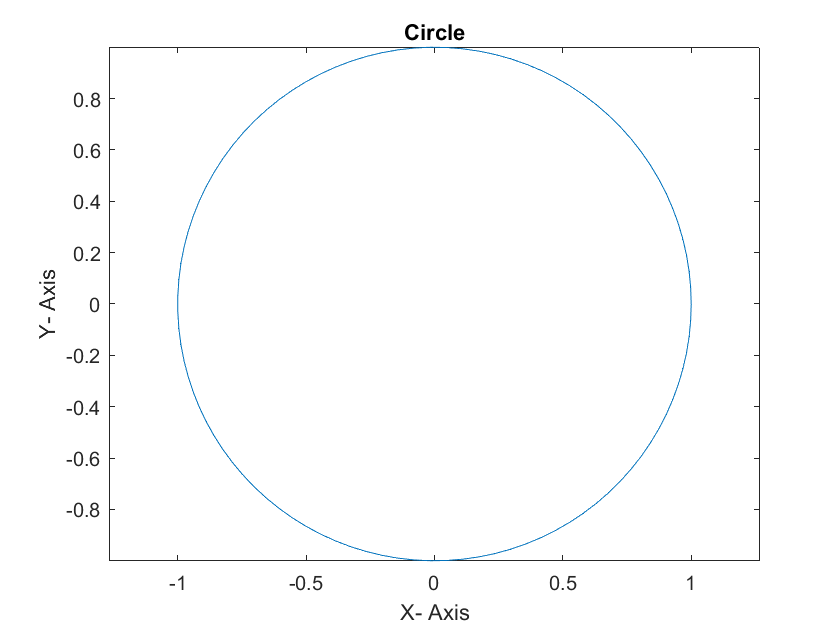

a1 = cos(T);
b1 = sin(T);
figure;
plot(a1,b1) % plotting a circle
xlabel('X- Axis') 
ylabel('Y- Axis')
title('Circle')
axis equal

Here, ***axis equal*** sets the aspect ratio so that the data units are the same in every direction.

## Plotting with different colours

The colours and the style should be specified as strings. The listed below are the colour codes.

- b blue.

- g green.

- r red.

- c cyan.

- m magenta.

- y yellow.

- k black.

- w white.

We can also set the style of the graph like '.', '-', etc. The colour code should be mentioned first and then the style should be mentioned.

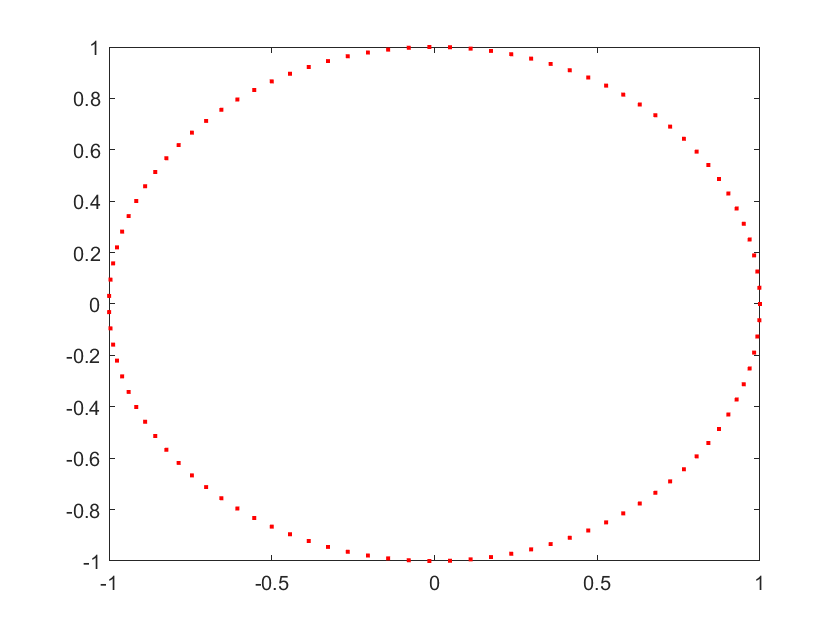

figure;
plot(a1,b1,'r.')

## Plotting multiple graphs in the same graph

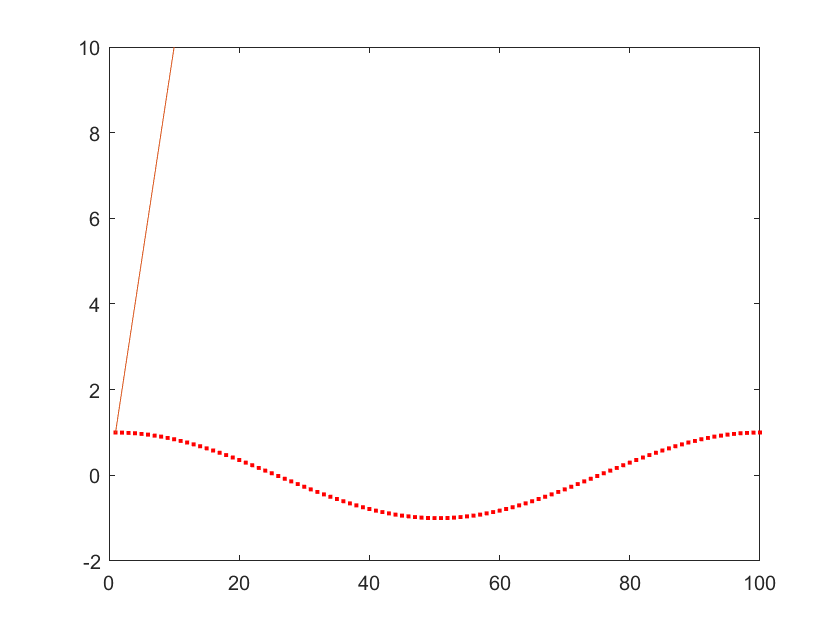

figure;
plot(a1,'r.')
hold on % using hold on command
c1 = 1:10;
plot(c1)
hold off

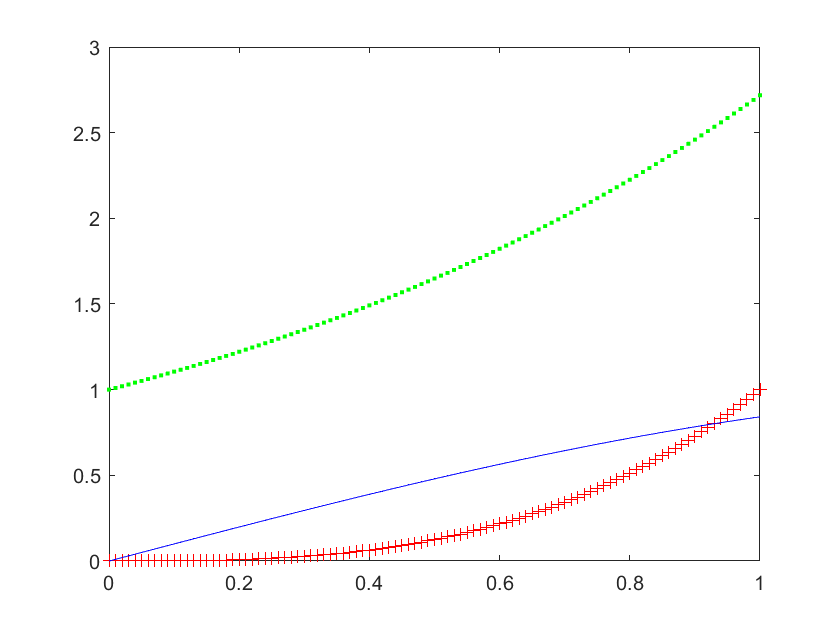

figure;
a = linspace(0,1,101);
plot(a,a.^3,'r+',a,sin(a),'b-',a,exp(a),'g.')

## Subplot in the same figure window

**Syntax:** subplot(row, column, sub figure at which place)

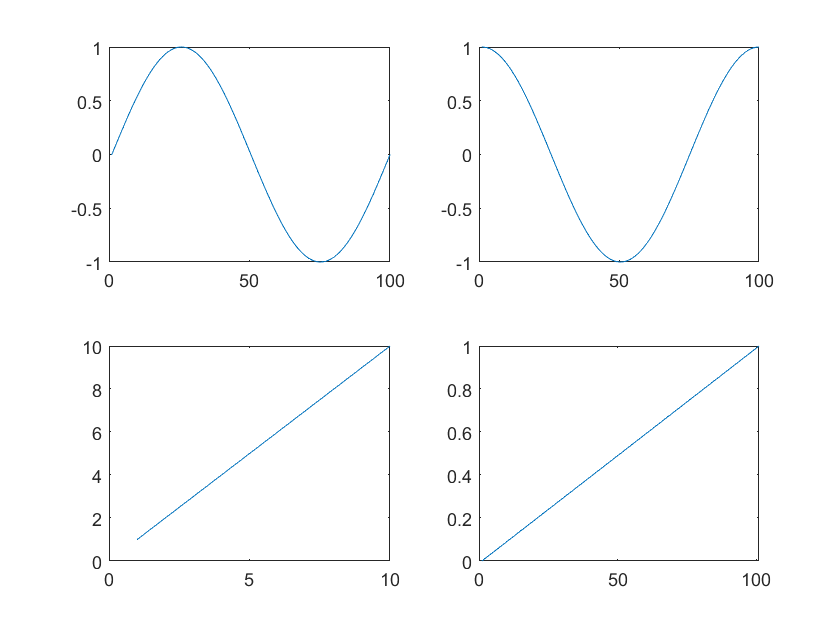

figure;
subplot(2,2,2)
plot(a1)
subplot(2,2,1)
plot(b1)
subplot(2,2,3)
plot(c1)
subplot(2,2,4)
plot(a)

## 3D plot

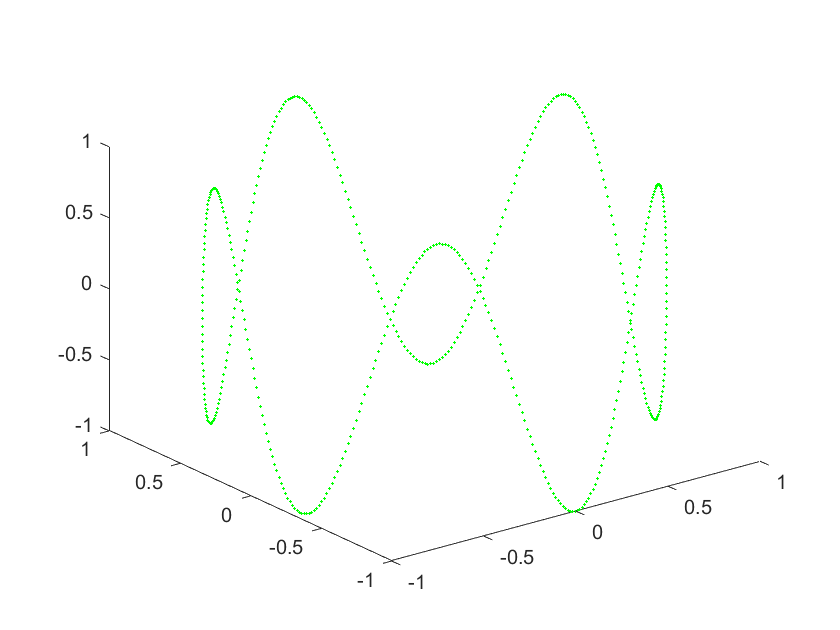

t=linspace(0,2*pi,500);
figure;
a1=cos(t);
b1=sin(t);
c1=sin(5*t);
% comet3(a1,b1,c1) it will be drawing live.
plot3(a1,b1,c1,'g*','markersize',1) %used to plot in 3D

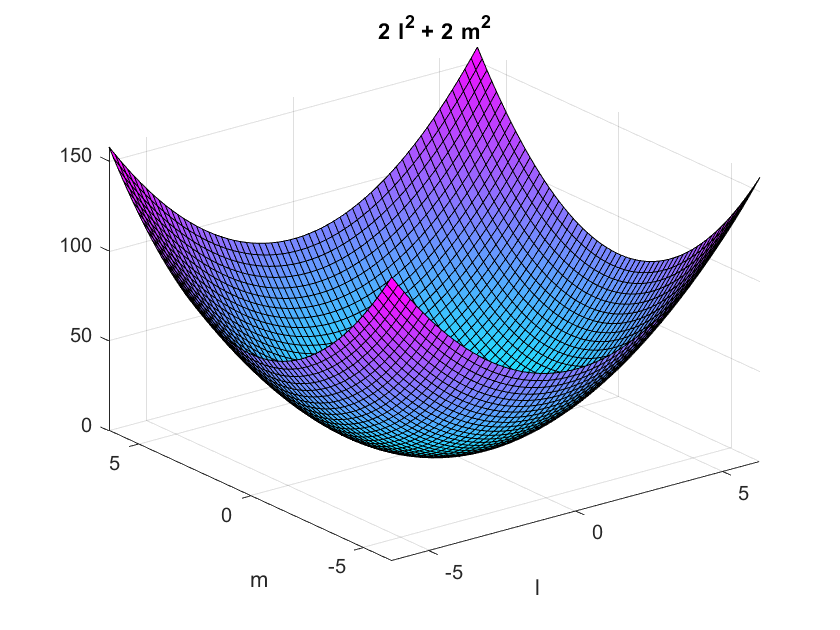

syms l m
figure;
f = 2*(l^2 + m^2);
ezsurf(f)
colormap cool

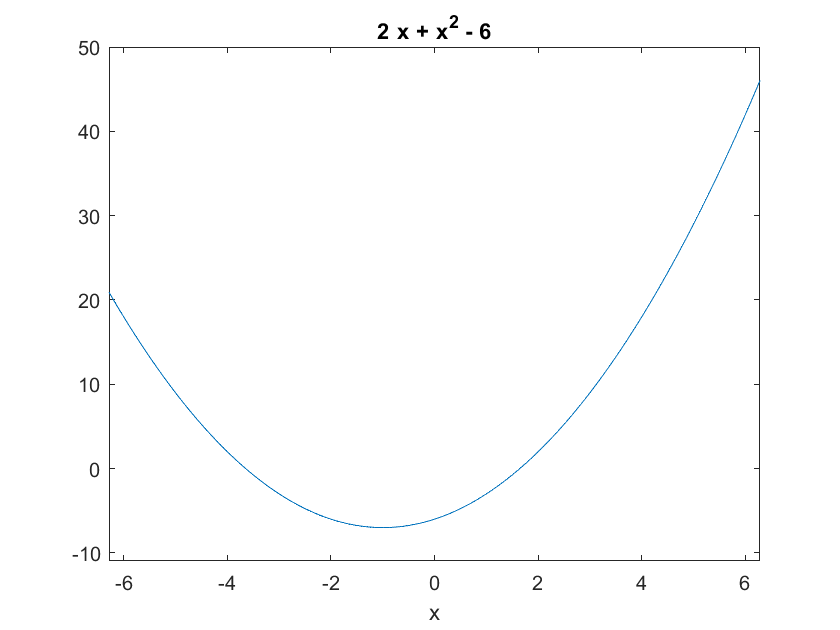

figure;
syms x 
y = x^2+2*x-6;
ezplot(y)

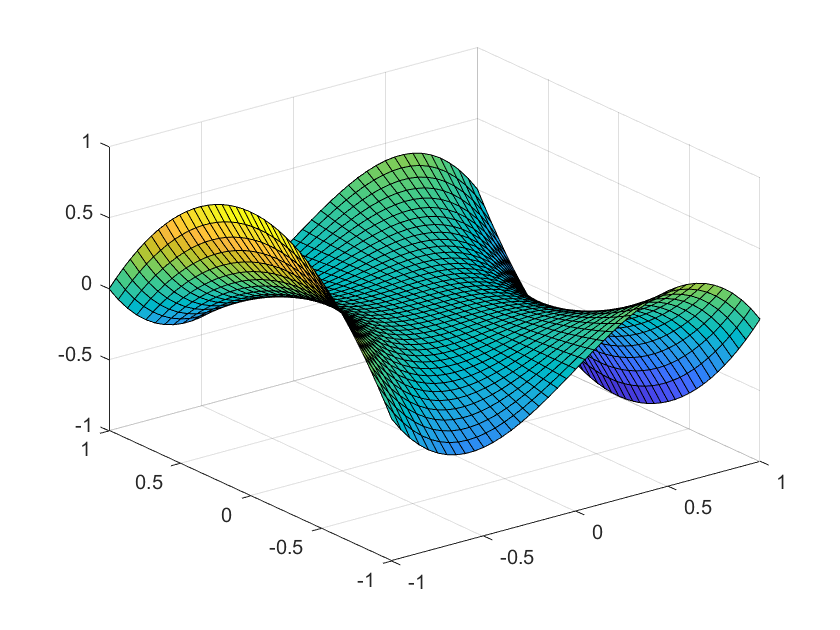

x2=-1:.05:1;
y2=-1:.05:1;
[x2,y2]=meshgrid(x2,y2);
z2=x2.*y2.^2-x2.^3;
surf(x2,y2,z2);

syms x % Declaring a symbolic variable
y=input ('enter the function f in terms of x:')
x1 = input('Enter x value at which tangent : ');
ezplot(y,[x1-2 x1+2]) % Easy Plotting
hold on
y_derivative = diff(y,x); % Differentiation in MATLAB
slope = subs(y_derivative,x,x1); % Finding the slope at the 
given point
y1 = subs(y,x,x1); % Finding the value of the function at the 
given point
plot(x1,y1,'r:*')
Tgt_line = slope*(x-x1)+y1 
h = ezplot(Tgt_line,[x1-2 x1+2]); % Plotting the Tangent Line
set(h,'color','r') % Coloring the Tangent Line
hold of